## 傅立葉變換 (Fourier Transformation)

## One dimensional DFT

a = [1 2 3 4 5];
F = fft(a')

F =   15.0000 + 0.0000i
  -2.5000 + 3.4410i
  -2.5000 + 0.8123i
  -2.5000 - 0.8123i
  -2.5000 - 3.4410i


f = ifft(F)

f =      1
     2
     3
     4
     5


接下來實作 DFT 的 linearity

f = [1, 4, 7, 9];
g = [5, 9, 0, 1];
h = 2*f + 3*g;
H = fft(h')

H =   87.0000 + 0.0000i
   3.0000 -14.0000i
 -25.0000 + 0.0000i
   3.0000 +14.0000i


F = fft(f');
G = fft(g');
2*F + 3*G

ans =   87.0000 + 0.0000i
   3.0000 -14.0000i
 -25.0000 + 0.0000i
   3.0000 +14.0000i


接著實作 DFT 的 shifting

a = [4, 1, 6, 7];
b = (-1).^(0:3).*a;
fft(a')

ans =   18.0000 + 0.0000i
  -2.0000 + 6.0000i
   2.0000 + 0.0000i
  -2.0000 - 6.0000i


fft(b')

ans =    2.0000 + 0.0000i
  -2.0000 - 6.0000i
  18.0000 + 0.0000i
  -2.0000 + 6.0000i


## 捲積 (Convolution)

matlab 中的 ***conv()*** 函數計算的是 $p(u)q(u)$ ，且我們可以發現 $p(u)(1 + u^N)$ 的值實際上就是把 array 中的係數重複一次，以下計算 a, b 的 convolution

N = 4;
a = [1, 2, 3, 4];
b = [5, 6, 7, 8];
r = conv(a, [b, b]);
result = r(N+1:2*N)

result =     66    68    66    60


以下實作 convolution theorem

rF = fft(result')

rF = 	1.0e+02 *

   2.6000 + 0.0000i
   0.0000 - 0.0800i
   0.0400 + 0.0000i
   0.0000 + 0.0800i


product = fft(a').*fft(b')

product = 	1.0e+02 *

   2.6000 + 0.0000i
   0.0000 - 0.0800i
   0.0400 + 0.0000i
   0.0000 + 0.0800i


## Two Dimensional DFT

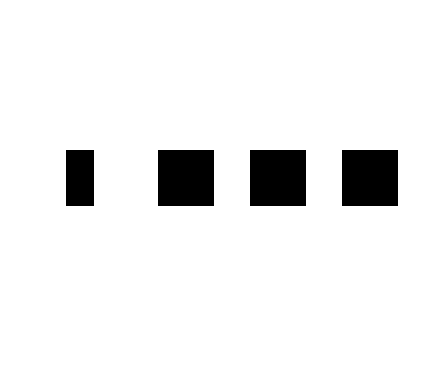

a = [zeros(256, 128) ones(256, 128)];
af = fft2(a);
shift_af = fftshift(af);
log_af = log(1 + abs(shift_af));
subplot(1, 4, 1); imshow(mat2gray(a));
subplot(1, 4, 2); imshow(mat2gray(abs(af)));
subplot(1, 4, 3); imshow(mat2gray(abs(shift_af)));
subplot(1, 4, 4); imshow(mat2gray(log_af));

第一張是模擬的影像，第二張是 Fourier Spectrum 但沒有經過 shift，可以發現整張圖都是黑的。第三張是經過 shift 之後，DC coefficient 移到中間，因此可以看到中間有一個白點就是 DC coefficient。第四張圖是將 Fourier Spectrum 重新 scale 之後，就可以看到其他的 pattern。

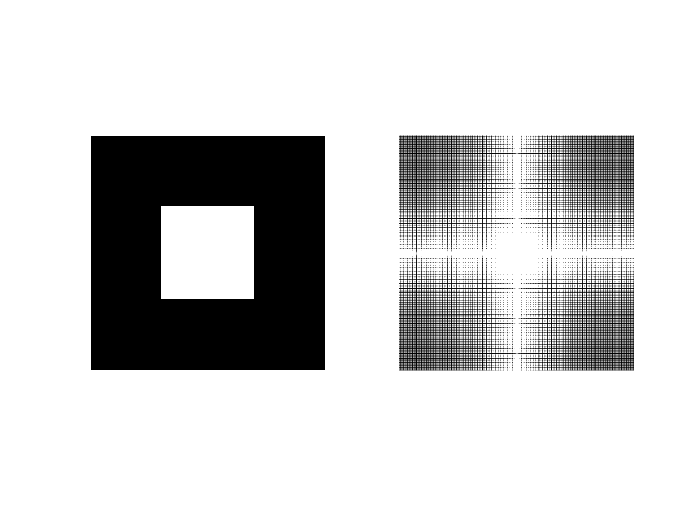

a  = zeros(256, 256);
a(78:178, 78:178) = 1;
ffta = log(1 + abs(fftshift(fft2(a))));
figure;
subplot(121); imshow(a);
subplot(122); imshow(ffta);

產生一個方形的頻譜，頻譜的中間點代表 frequency 較低的位置，外圍則是 frequency 較高的位置。接著嘗試旋轉正方形之後的頻譜。

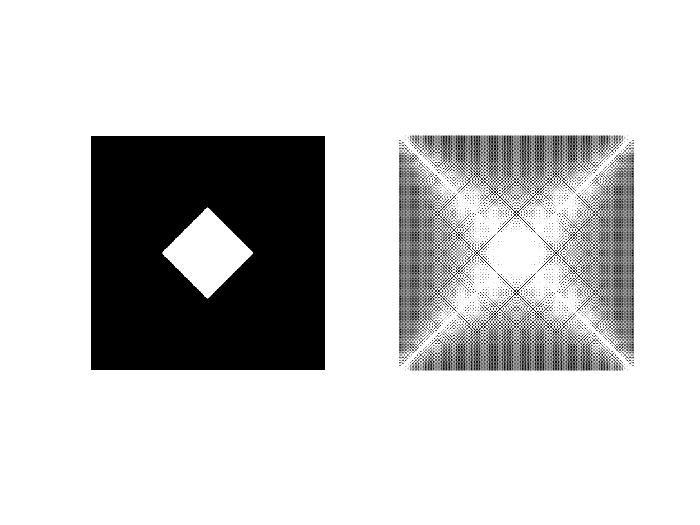

rotate_a = imrotate(a, 45, "bicubic");
ffta_rotate = log(1 + abs(fftshift(fft2(rotate_a))));
figure;
subplot(121); imshow(rotate_a);
subplot(122); imshow(ffta_rotate);

可以看到 spectrum 也會跟著旋轉。

## Two Dimensional DFT with real Image

所以我們知道在做完 shift 之後，Fourier Spectrum 的中間是 image 的 low freq 部分，外圍是 high freq 部分，因此使用 mask 來對 Fourier Spectrum 做 spatial filter 之後再用 inverse Fourier Transform 就能達到 low pass filter 跟 high pass filter 的效果。

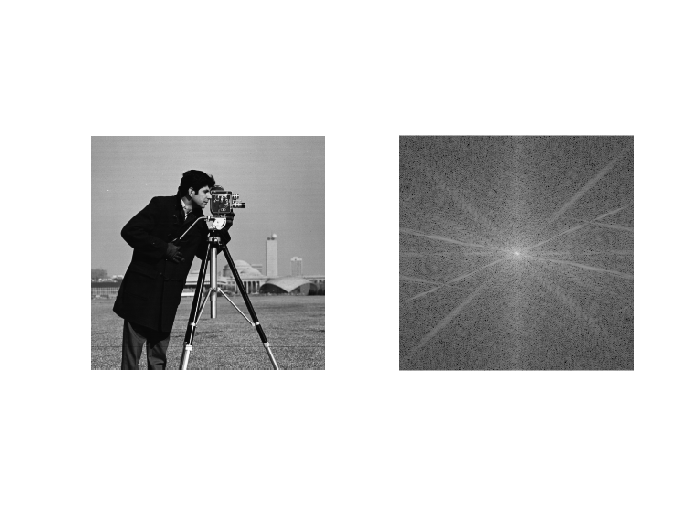

img = imread("Image\cameraman.png");
fft_img = fftshift(fft2(img));
figure; 
subplot(121); imshow(img);
subplot(122); imshow(mat2gray(log(1 + abs(fft_img))));

左邊是原圖，右邊是他的 Fourier Spectrum

接著我們創造一個 filter 來過濾 Fourier Spectrum，再用 inverse FFT 把 spectrum 轉回去

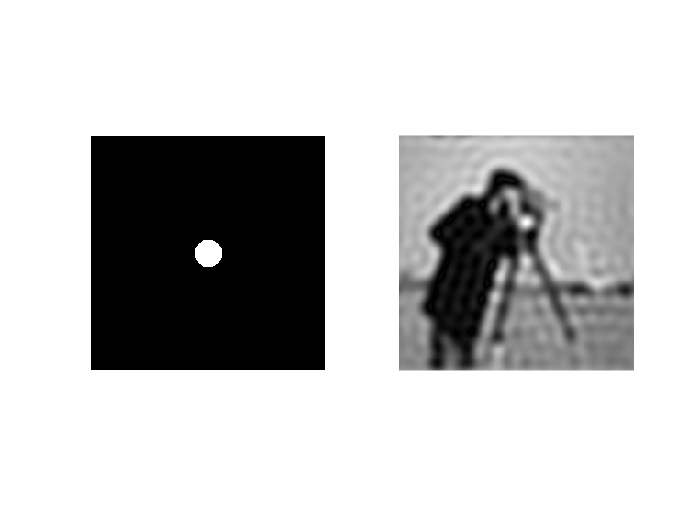

[x, y] = meshgrid(-128:127, -128:127);
z = sqrt(x.^2 + y.^2);
c = (z < 15);
filt = c.*fft_img;
f_img = mat2gray(abs(ifft2(filt)));
figure;
subplot(121); imshow(abs(filt));
subplot(122); imshow(f_img);

可以看到達到 low pass filte 的效果，因此調整這個圓圈的大小，就可以做出不同強度的 low pass filter。

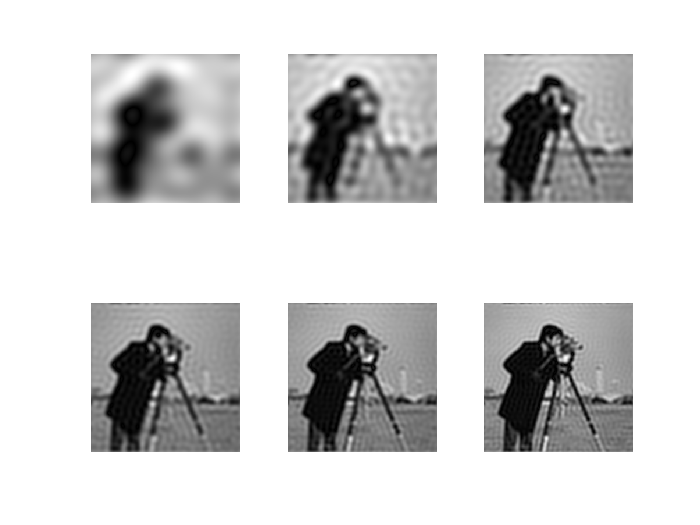

count = 1;
figure;
for i = [5 10 15 20 25 30]
    c = (z < i);
    filt = c.*fft_img;
    f_img = mat2gray(abs(ifft2(filt)));
    subplot(2, 3, count); imshow(f_img);
    count = count + 1;
end

當圓圈的半徑越小時，他就會是越強的 low pass filter，所以可以看到一開始的圖是比較模糊的，然後隨著圓越來越大，圖逐漸變清晰。

同理我們也可以做出 high pass filter

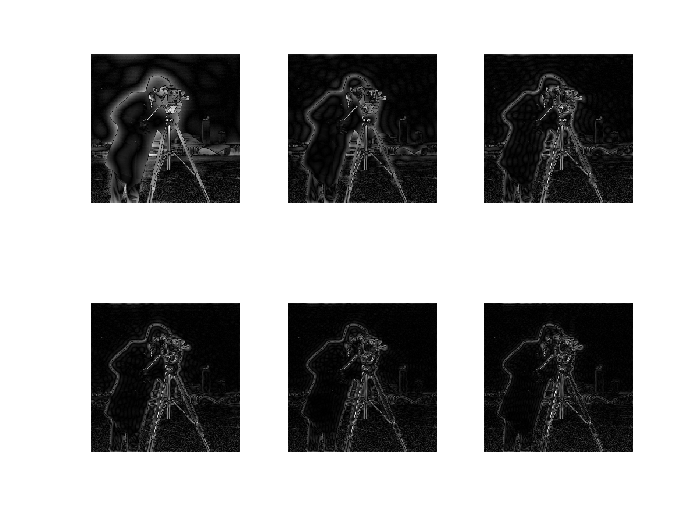

count = 1;
figure;
for i = [5 10 15 20 25 30]
    c = (z > i);
    filt = c.*fft_img;
    f_img = mat2gray(abs(ifft2(filt)));
    subplot(2, 3, count); imshow(f_img);
    count = count + 1;
end

但這種作法有一個缺點，就是他會直接把值 cutoff 造成 inverse 後的影像會有波紋。一種 alternative 的方法就是不要 cutoff ，而是藉由 grid 到 center 的距離來決定 weight。這種方法稱作 Butterworth Filter。例如一個切點為 d 的 low pass filter 可以寫成

                                            
$$f(x, y) = 1, if \sqrt{x^2 + y^2} < d \;\; else \;\;0$$


而 Butterworth Filter 便為

                                     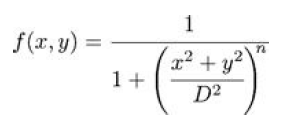

其中 D 為 cutoff pint, n 為在 cutoff point 的變化程度。下面令 $D = 15$, $n = 3$，與其跟 ideal filter 比較

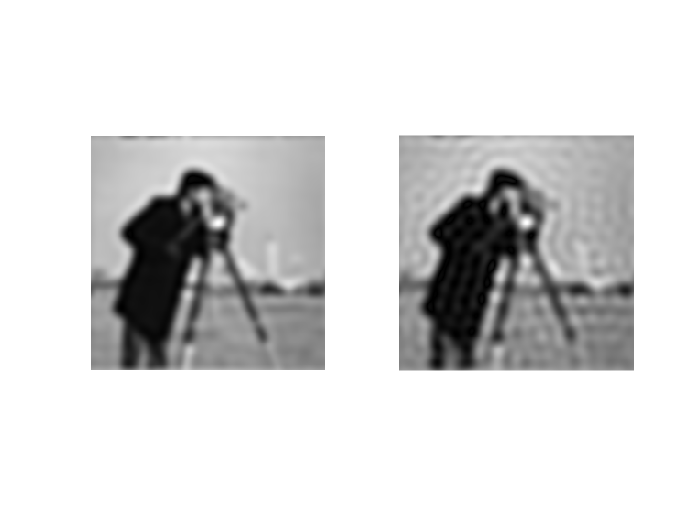

D = 15;
n = 3;
butterworth = 1 ./ (1 + ((x.^2 + y.^2) / D^2).^n);
ideal = (z < D);
bw_img = mat2gray(abs(ifft2(butterworth.*fft_img)));
ideal_img = mat2gray(abs(ifft2(ideal.*fft_img)));
figure;
subplot(121); imshow(bw_img);
subplot(122); imshow(ideal_img);

可以看到使用 Butterworth Filter，在 cutoff point 相同的情況下，波紋的情況比 ideal filter 好很多。同樣的，Butterworth Filter 也可以應用到 high pass filter，其 function 為

                                        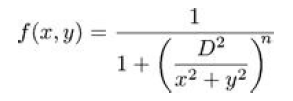

下面同樣比較 $D = 15, n = 3$ 的 Butterworth Filter 跟 ideal filter

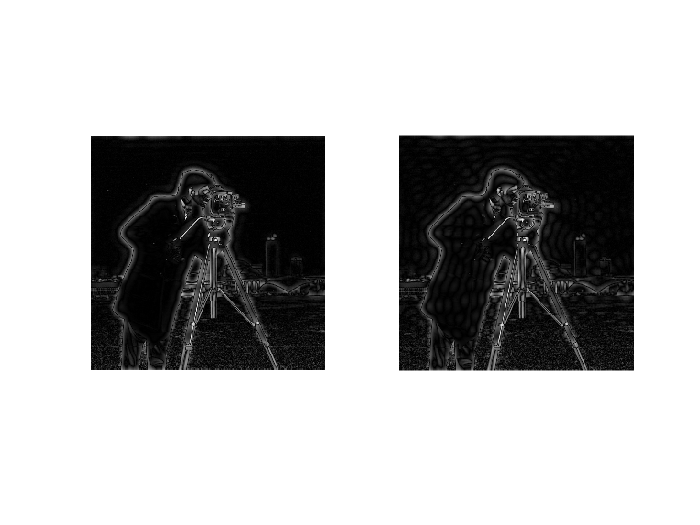

butterworth_high = 1 ./ (1 + (D^2 ./ (x.^2 + y.^2)).^n);
ideal = (z > D);
bw_img = mat2gray(abs(ifft2(butterworth_high.*fft_img)));
ideal_img = mat2gray(abs(ifft2(ideal.*fft_img)));
figure;
subplot(121); imshow(bw_img);
subplot(122); imshow(ideal_img);

由於使用 high pass filter 得到的影像大部分都是黑的，所以看不到清楚波紋的表現，下面把圖片變亮一點以便觀察。

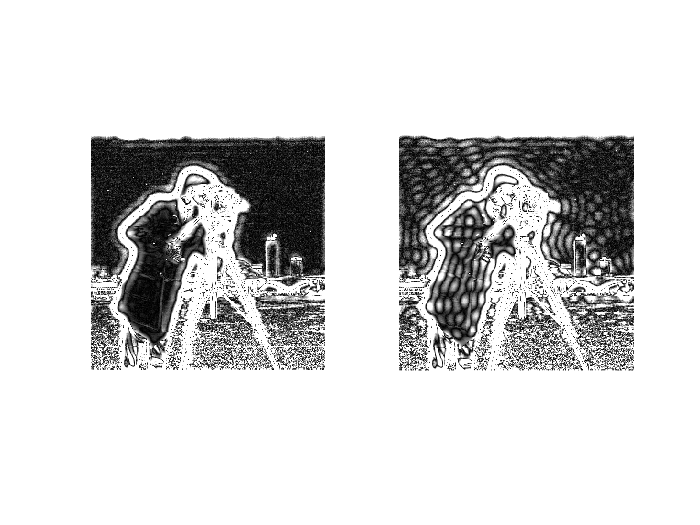

figure;
subplot(121); imshow(bw_img * 10);
subplot(122); imshow(ideal_img * 10)

可以看到使用 Butterworth Filter 的波紋情況比使用 ideal filter 好很多。下面比較不同的 $n$，也就是切點的變化率所得到的結果

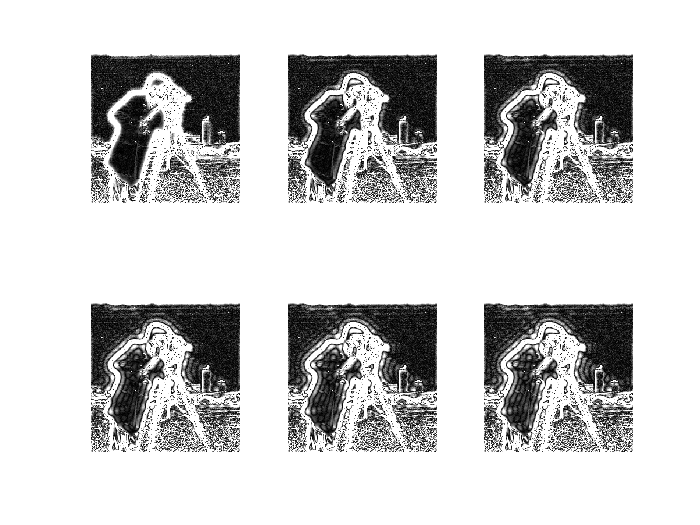

figure;
nl = [1 3 5 7 9 11];
for i = (1:6)
    n = nl(i);
    butterworth_high = 1 ./ (1 + (D^2 ./ (x.^2 + y.^2)).^n);
    bw_img = mat2gray(abs(ifft2(butterworth_high.*fft_img)));
    subplot(2, 3, i);
    imshow(bw_img * 10);
end

可以看到當 $n$ 越大時，代表邊界變化越快速，此時 Butterworth Filter 會越接近 ideal filter，波紋變會漸漸出現。

## Gaussian Filter

剛剛是用 Butterworth Filter，但也可以使用 Gaussian Filter 來過濾達到 Low Pass Filter 的效果，Gaussian Filter 是這幾種 filter 裡面最平滑的。以下使用不同標準差的 Gaussian Filter 來過濾 Fourier Spectrum

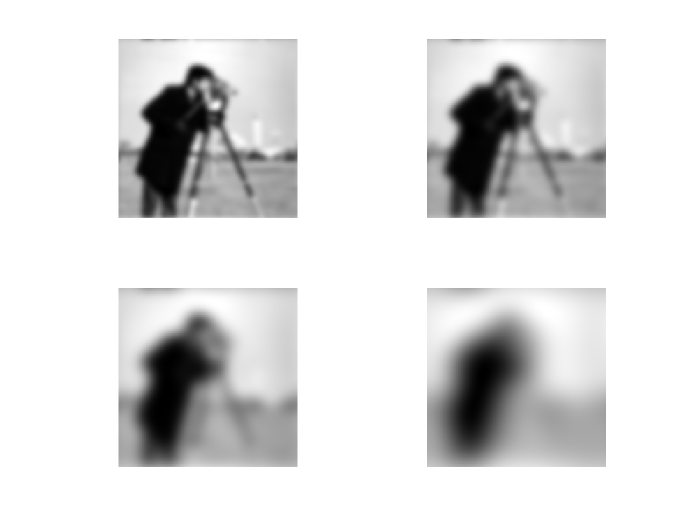

sigma = [10 7 4 2];
figure;
for i = (1:4)
   g = fspecial("gaussian", 256, sigma(i));
   gau_img = mat2gray(abs(ifft2(g.*fft_img)));
   subplot(2, 2, i);
   imshow(gau_img);
end

可以看到隨著標準差越小，模糊的程度越高，而且使用 Gaussian Filter 可以完全免除掉波紋的情形。

## Homomorphic FIltering

當影像有出現部分區域過曝、部分區域過暗，我們可以採用 homomorphic filtering，概念基本上就是將 intensity range 縮小將低明度，並且同時增加區域亮度。注意這種情況不能用 histogram equalization，因為圖片已經有對比，只是對比過大。

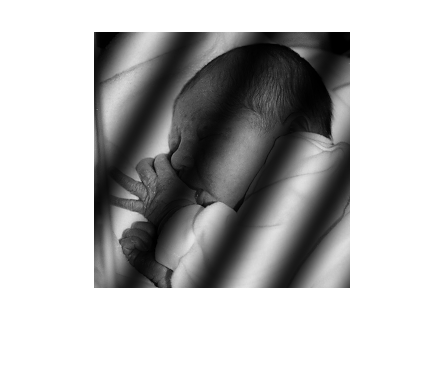

img = im2double(imread("Image\newborn.png"));
[x, y] = meshgrid(1:256, 1:256);
img_sin = img.*(0.5 + 0.4*sin((1.3*x + 0.7*y - 50) / 16));
figure; imshow(img_sin);

這裡用 sin function 創造了一個明暗對比過大的圖，接著用 Fourier Transformation 實現 homomorphic filtering

imghom = homfilt(img_sin, 128, 2, 0.5, 2);
figure; imshow(imghom/14);

可以看到我們稍微地增加黑色條紋的亮度了。

function res = homfilt(im, cutoff, order, lowgain, highgain)
    u = im2uint8(im);
    height = size(im, 1);
    width = size(im, 2);
    [x, y] = meshgrid(-floor(width/2) : floor((width - 1)/2), -floor(height/2) : floor((height - 1)/2));
    lbutter = 1 ./ (1 + (sqrt(2) - 1)*((x.^2 + y.^2)/cutoff^2).^order);
    u(find(u == 0)) = 1;
    lg = log(double(u));
    ft = fftshift(fft2(lg));
    hboost = lowgain + (highgain - lowgain)*(1 - lbutter);
    b = hboost.*ft;
    ib = abs(ifft2(b));
    res = exp(ib);
    
end